# Plot Sensitivities

- Load the symbolic char parameters and the sensitivities to plot

- Plot Sensitivities

#### Step 1

clear; 
clear all;

Parameters;
load("mats/SIE_X_Means.mat", "SIE_X_Means");
load("mats/SIE_X_Sensitivities.mat", "SIE_X_Sens");
load("mats/AIE_X_Means.mat", "AIE_X_Means");
load("mats/AIE_X_Sensitivities.mat", "AIE_X_Sens");

#### Step 2

Now that we have loaded the sensitivities and necessary character values, we can plot the:

- SIE and AIE sensitivies

- Means of SIE and AIE - Heatmap, ascending order of parameter influence

#### SIE and AIE Sensitivities

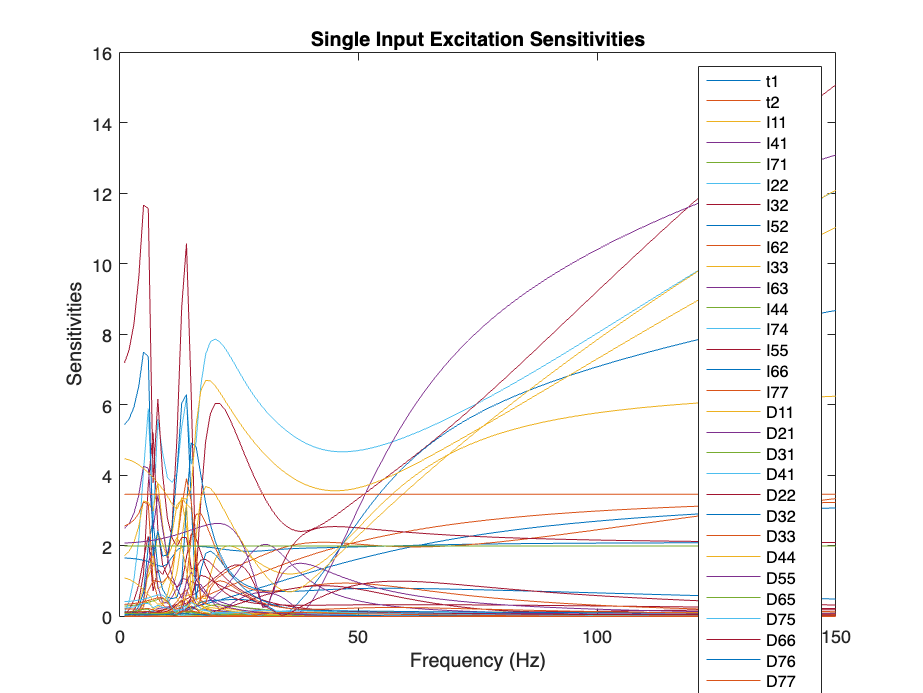

% SIE and AIE
sens_x_plot(SIE_X_Sens, "Single Input Excitation Sensitivities", params_char);

saveas(gcf, "figs/SIE_X_Sensitivities", "fig");

Error using saveas
Invalid or missing path: figs/SIE_X_Sensitivities

sens_x_plot(AIE_X_Sens, "All Input Excitation Sensitivities", params_char);
saveas(gcf, "figs/AIE_X_Sensitivities", "fig");

We just plotted the sensitivities, now lets plot their means so we can analyze which parameters have the most effect in the tremor band.

#### SIE and AIE Mean Sensitivities

% Go into individual sensitivities
mean_x_plot(SIE_X_Means, "Mean of Single Input Excitation Sensitivities", params_char);
saveas(gcf, "figs/Mean_SIE_X", "fig");
mean_x_plot(AIE_X_Means, "Means of All Input Excitation Sensitivities", params_char);
saveas(gcf, "figs/Mean_AIE_X", "fig");